# ENGR3390: Fun-Robo ACT Lab: Servos

Elvis Wolcott and Jackie Zeng

Created 2/17/2021 - Revision 1

**Demonstration of using RCServoArduino()**

Aims a laser pointer using two servo motors attached to an Arduino-like microcontroller using PWM.

Works with the Spark Fun Wireless Motor Driver (DEV-14285), but should work with any Arduino setup wired the same.

The pan motor should be connected to PWM 9 and tilt to PWM 11.

The laser pointer should be connected to Digital 12.

The program prompts for positions 0-1 and then sets the position of the servo. Different servos have different ranges of motions, so we will measure the actual range and enter it to the program to produce a calibration graph.

## Document Code

clc
clear

## Stuff you run once

% COM port (CHECK THIS ON YOUR SYSTEM!)
port = 'COM12';         % Elvis
%port = 'COM4';          % Jackie
disp('note: It takes about 10 seconds to download new code to the Arduino');

note: It takes about 10 seconds to download new code to the Arduino


[robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(port);
% blink the on board LED
Blink(robotArduino, blinkLED, 3);
disp("Warning: Pan and Tilt Servos Active!");

% collected data
nTests = input(['Enter number of servo test positions, ' ...
    'followed by enter: ']);

% create a variable to hold experimental position data
panServoData = zeros(nTests,2);
tiltServoData = zeros(nTests, 2);

r = rateControl(0.25);                % create a 0.25 hz loop rate
reset(r);                             % reset loop time to zero

## Stuff you run multiple times

% test loop that collects samples
controlFlag = 1;                % loop progress
while (controlFlag < nTests+1)  % loop until flag is unset
    commandAngle = SENSE();     % desired angle from operator (used for both)
    panAngle = commandAngle;
    tiltAngle = commandAngle;
    THINK();                    % no op
    
    % set servo positions
    ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);
    
    % store requested and actual positions
    panServoData(controlFlag, 1) = input("Enter actual pan angle (degrees):");
    panServoData(controlFlag, 2) = panAngle;
    tiltServoData(controlFlag, 1) = input("Enter actual tilt angle (degrees):");
    tiltServoData(controlFlag, 2) = tiltAngle;
    
    % blink to indicate completion
    Blink(robotArduino, blinkLED, 1);
    
    % loop iteration
    waitfor(r);
    controlFlag = controlFlag + 1;
end

## Mission Data Processing

plot(panServoData(:, 1), panServoData(:, 2), '-*');
hold on;
plot(tiltServoData(:, 1), tiltServoData(:, 2), '-*');
hold off;
xlabel('Actual Angle');
ylabel('Commanded Angle');
legend('Pan Servo', 'Tilt Servo');

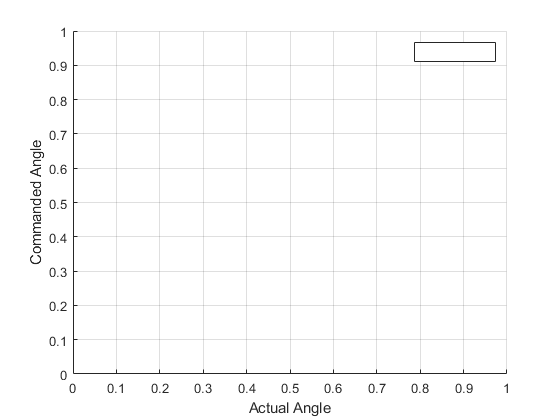

grid;

% save calibration panServoData tiltServoData

## Test Angles

Run this section with different values to test different angles

panAngle = SENSE_panAngle();
tiltAngle = SENSE_tiltAngle();

% set servo positions
ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);
laserOn(robotArduino);

laserOff(robotArduino);

## Test XY Position

Run this section with different XYs to move laser to diff parts of the wall. Make sure to turn off the laser after testing. 

(0,0) is straight in front of the robot. 

[panAngle, tiltAngle] = SENSE_XY(25);
% set servo positions
ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);

laserOn(robotArduino)

laserOff(robotArduino);

## Test Draw Square

The last input argument is how many times you want to draw the square

DrawSquare(robotArduino, panServo, tiltServo, 10);

## Load Complex Drawing

The points are generated using the HTML file in this directory (because MATLAB doens't have a easy way to process SVG files).

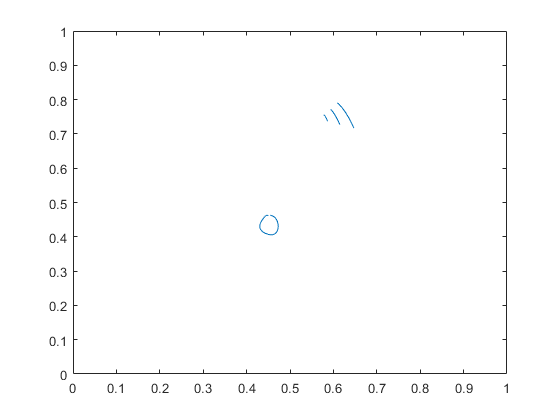

Unrecognized function or variable 'panServo'.

Error in PositionControlRCServo>draw (line 165)
            ACTRCServoArduino(panServo, tiltServo, pan, tilt);

drawing = readtable("./garf.svg.csv");
figure();

% show it just for visual confirmation
plot(table2array(drawing(:, 1)), table2array(drawing(:, 2)))
ylim([0, 1]);
xlim([0, 1]);
% draw it
draw(drawing, 24);

## Function Storage

function [robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(COMPORT)
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');
    
    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, "DigitalOutput");
    LASER = 'D12';
    configurePin(robotArduino, LASER, "DigitalOutput");
    
    panServo = servo(robotArduino, 'D9', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    tiltServo = servo(robotArduino, 'D11', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    
    % straight ahead
    writePosition(panServo, 0.77);
    writePosition(tiltServo, 0.5);
    pause(5.0)
end

function [] =  Blink(a, LED, n)
    for bIndex=1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2)
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

function [] = DrawSquare(robotArduino, panServo, tiltServo, COUNT)
    % delay (seconds) between movements
    DELAY = 0.1; % much faster and it won't be a square!
    
    % turn on the laser
    laserOn(robotArduino);
    
    % coordinates of box
    y1 = 0.68;
    y2 = 0.7;
    x1 = 0.77;
    x2 = 0.75;
    % initial position
    writePosition(tiltServo, y1);
    writePosition(panServo, x1);
    
    % draw a square
    counter = 0;
    while (counter < COUNT)
        % draw the sides
        pause(DELAY);
        writePosition(tiltServo, y2);
        pause(DELAY);
        writePosition(panServo, x2);
        pause(DELAY);
        writePosition(tiltServo, y1);
        pause(DELAY);
        writePosition(panServo, x1);
        counter = counter + 1;
    end
    
    % turn off the laser
    laserOff(robotArduino);
end

function [] = draw(paths, distance)
    % points are generated with svg2points
    % only paths work and closed paths bug out (do to how browsers handle
    % them)
    % points are provided normalized (0-1) and evenly spaced along the
    % drawing (to produce consistent detail)
    % to get consistent drawing speed however, the spacing of points needs
    % to be adjusted based on the angular distance traveled
    % paths is an array of point lists
    % this is accomplished by determining the angle to turn between two
    % points and interpolating for consistent speed
    for i=1:size(paths, 1)
        row = paths(i,:);
        x = row{1, 1};
        y = row{1, 2};
        % -1 is a laser command
        if x == -1
            if y == 0
                laserOn(robotArduino)
            end
            if y == 1
                laserOff(robotArduino)
            end
        else
            % otherwise it's a point to draw
            [pan_deg, tilt_deg] = SENSE_XY(distance);
            [pan, tilt] = deg2ctrl(pan_deg, tilt_deg);
            ACTRCServoArduino(panServo, tiltServo, pan, tilt);
            pause(0.01); % TODO: uniform movement speed
        end
    end
end

**Sense Functions**

function commandAngle = SENSE()
    commandAngle = input('Enter desired angle (from 0 to 1): ');
end

function panAngle = SENSE_panAngle()
    panAngle = input('Enter desired pan angle (from -30 to 30 degrees): ');
end

function tiltAngle = SENSE_tiltAngle()
    tiltAngle = input('Enter desired tilt angle (from -30 to 30 degrees): ');
end


function [pan_deg, tilt_deg] = SENSE_XY(dist_wall)
    % dist_wall is the distance from the wall in feet
    % dist_wall == 24 ft when I checked it last
    
    angle_range = 30;                    % pan and tilt can both move in the range -30 to 30 deg
    x_range = tand(angle_range)*dist_wall;
    hyp = sqrt(dist_wall^2 + x_range^2);
    y_range = tand(angle_range)*hyp;
    
    % Get user inputs x and y in ft. (0,0) is straight in front of the robot.
    x = input(['Input x in range of +- ' num2str(x_range) ' ft:  ']);    % get user input x            
    y = input(['Input y in range of +- ' num2str(y_range) ' ft:  ']);    % get user input y
    new_hyp = sqrt(dist_wall^2 + x^2);
    
    pan_deg = atand(x/dist_wall);
    tilt_deg = atand(y/new_hyp);
end

**Think Functions**

function THINK()
end

function [panAngle, tiltAngle] = deg2ctrl(deg_panAngle, deg_tiltAngle)
    % Limit pan range to be from 0.46 to 1, with 0.73 being pointing front. The
    % reason why 0.5 is not front is because the motor is mounted offcentered.
    panAngle = ((deg_panAngle+30)/60)*(1-0.46) + 0.46;
    % Limit tilt range to be from 0.3 to 1, with 0.65 pointing parallel to the floor.
    tiltAngle = (((-deg_tiltAngle)+30)/60)*(1-0.3) + 0.3;
end

**Act Functions**

function ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle)
    [panAngle, tiltAngle] = deg2ctrl(panAngle, tiltAngle);
    
    % set position of two servos
    writePosition(panServo, panAngle);
    writePosition(tiltServo, tiltAngle);
end

function [] = laserOn(robotArduino)
    % turn on the laser
    LASER = 'D12';
    writeDigitalPin(robotArduino, LASER, 1);
end

function [] = laserOff(robotArduino)
    LASER = 'D12';    
    writeDigitalPin(robotArduino, LASER, 0);
end